# Matlab eta limiteak

Matlab matematika egiteko software oso erabilia da. Matlaben textua idazteko portzentajea idazten da textuaren aurretik. Testu hori ez da konpilatuko. Gainera, programa atal ezberdinetan bana daiteke. Horretarako, nahikoa da portzentai bikoitza erabiltzea. 

clear all %Lehen zegoen guztia ezabatzeko

## Matlaben zenbakiekin lan egiten

Matlaben balioak gorde daitezke aldagaietan. Balioak izan daitezke zenbakiak, bektoreak, matrizeak, funtzioak... Zentra gaitezke zenbakietan:

a=1

a = 1

Fijatzen bazara, emaitza konpilatzean, komando lehioan emaitza ateratzen da. Hori ez gertzeko, nahikoa da bukaeran puntu eta koma ez jartzea; adibidez:

b=2;

Matlab predefinitutako funtzio asko ditu. Kalkuluak egiteko orduan askotan erabiliko dugu **sin**, **cos**, **tan**, **exp** eta **log** (logaritmo neperianoa). Gainera, $\pi$ memorian gordera du **pi **aldagaian. Adibidez

exp(a)

ans = 2.7183

log(a)

ans = 0

cos(pi)

ans = -1

Matlaben, batuketak, kenketak, biderketak, zatiketak, berredurak egin daitezke:

a+b

ans = 3

b-a

ans = 1

b*a

ans = 2

b/a

ans = 2

b^5

ans = 32

Bide batez, eragiketa azkar bat egin behar baduzu, idatz dezakezu komando lehioan zuzenean, command window jartzen duen lekua. 

## Matlaben bektoreekin lan egiten

Matlabek ahabidetzen du zenbaki bektoreak definitzea. Adibidez,

u=[1 2 3 4 5]

u =      1     2     3     4     5


v=[6 7 8 9 10]

v =      6     7     8     9    10


Bektoreekin batuketak eta kenketak egin ditzakegu gaiz gai.

v+u

ans =      7     9    11    13    15


v-u

ans =      5     5     5     5     5


Bektoreen biderketa eskalarra egin dezakegu

dot(v,u)

ans = 130

Gainera, ere egin dezakegu biderketa, zatiketa edo berreketak gaiz gai. Horreterako **.*** eta **./** komandoak erabili behar ditugu. ***** eragileak matrize arteko biderketa egiten du; hortaz, errorea emango dizue

v.*u

ans =      6    14    24    36    50


v./u

ans =     6.0000    3.5000    2.6667    2.2500    2.0000


u.^2

ans =      1     4     9    16    25


Batzutan, bektore berezi batzuk definitu behar dira; adibidez, $n$-tik $m$-ra doan bektorea $k$ tamainako pausuak emanda, **n:k:m**. $k$ izan daiteke positibo edo negatibo. **n:m** idatziz gero, $k=1$ hartuko du.

w1=1:2:51

w1 =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51


w2=100:100:10^6;

Azkenik bektore baten **k.** gaia parentesi batekin lor dezakegu:

w1(1)

ans = 1

w2(5)

ans = 500

## Matlaben funtzioetan lan egiten

Matlaben ere defini ditzakegu funtzioak. Defektuzko egitura honako hau da:  izena= **@**(aladagaik) funtzioa

f1= @(n) (n+(-1).^n)./(n-(-1).^n);

Aldagaien izenak izan daiteke $n$, $x$ edo nahiago duzuena. Puntuak egotea ahalbidetuko dugu funtzioak bektoreetan ebaluatzea. Horrela, eragitak gaiz gai ebaluatuko dira. Adibidez,

f1(5)

ans = 0.6667

f1([1 2 3 4 5])

ans =          0    3.0000    0.5000    1.6667    0.6667


Behin funtzioa definituta dagoenean, komando lehioan defini daiteke. Azkenengo aukera bat da aldagai batean gordetzea, eta workspace (begiratu eskuinera) begiratzea zer gertatzen den balioekin:

an1=f1(1:10000)

an1 =          0    3.0000    0.5000    1.6667    0.6667    1.4000    0.7500    1.2857    0.8000    1.2222    0.8333    1.1818    0.8571    1.1538    0.8750    1.1333    0.8889    1.1176    0.9000    1.1053    0.9091    1.0952    0.9167    1.0870    0.9231    1.0800    0.9286    1.0741    0.9333    1.0690    0.9375    1.0645    0.9412    1.0606    0.9444    1.0571    0.9474    1.0541    0.9500    1.0513    0.9524    1.0488    0.9545    1.0465    0.9565    1.0444    0.9583    1.0426    0.9600    1.0408


Workspacen ere argi ikus daiteke limitea, eta segida nola konportatzen den. Guztiz ikusteko, open erabili dezakezu:

open("an1")

## Matlabekin limitea balio handia hartuz kalkulatzen

Matlab erabili dezakegu segida baten limitea enpirikoki kalkulatzeko. Aukera bat da segida bat hartzea eta balio handiak hartzea. Horretarako, gogoratu behar dugu Matlab zenbakiak laburtzen dituela erakusteko; hortaz, nahikoa da format long idaztea digitu Matlaben lan egiten dituen digituak berrezkuratzeko. Bestalde, format short idatz dezakegu lau digituetara itzultzeko.

format long
f1= @(n) (n+(-1).^n)./(n-(-1).^n);
f1([100,1000,10^4,10^5, 5*10^5,10^6,5*10^6,10^8])

ans =    1.020202020202020   1.002002002002002   1.000200020002000   1.000020000200002   1.000004000008000   1.000002000002000   1.000000400000080   1.000000020000000


Balioak harturik, ikus daiteke $1$erantz jotzen duela. Noski, hau ez da froga matematiko bat. Aitzitik, modu heuristiko batean frogatutako baieztapen bat da. Bigarren aukera bat da grafo bat egitea segidarekin. Horrekin ikus daiteke gutxi gora behera zein den limitea. Horretarako, stem komandoa erabil daiteke segida bat irudikatzeko.

stem(f1(1:10000))

Grafoan ez da gehiegirik ikusten, baina bukaeran zoom eginez gero modu heuristiko batean froga daiteke limitea $1$ izango dela. Bide batez, grafikoan gauzak hobeto ikusteko esan ahal diogu Matlabi ardatzei paraleloak diren lerro batzuk irudikatzeko. Horretarako grid on komandoa erabili behar da.

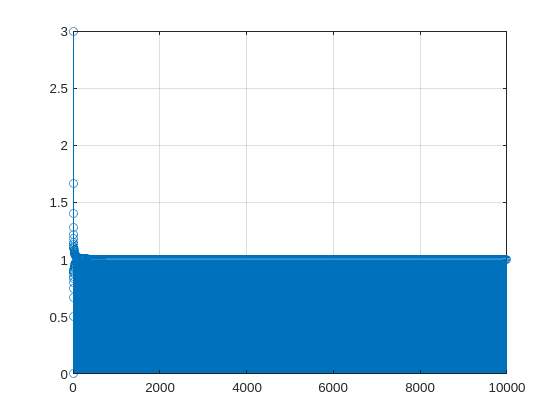

grid on 

Lerroak kentzeko, noski, grid off erabili behar da. Hori bai, komandu hau idatzi behar da grafiko baten ostean, ez da mantentzen hurrengo grafikorako

format short 

Matlab zenbaki laburtuak itzultzeko. Gauzak hobeto ikusteko aukera daitezke puntu batzuk; adibidez,

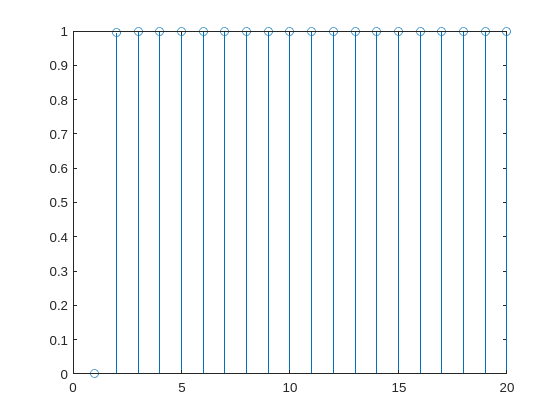

stem(f1(1:500:10000))

Noski, puntuak kentzean segidaren informazioa gal dezakegu. Hemen irudi dezake segida gorakorra dela; baina ez da hala. Kontua da, bikoitietan beherakorra dela eta gorakorra bakoitietan. Edonola ere, modu heuristiko batean justifikatzeko limitea bat dela balio ahal digu grafiko hau. **grid on** idatzi behar da grafiko guztien ostean. Bestela, lerro horiek kenduko ditu hurrengo grafikoa egitean.

## Matlab kalkulo sinbolikoa.

Azkenik, Matlabek kalkula ditzake limitea, programatuta dago hori egiteko. Hori ez da hain atsegina limiteak zein diren ulertzea baino, baina oso praktikoa suerta ahal zaizue. Horretarako, modu sinbolikoan egin behar dugu lan Matlabekin. Horretarako, esan behar da n aldagai simbolikoa dela;  hots, balioa ez dakigun aldagai bat dela. Matlabekin egin daitezke eragiketak euren balio zehatza ez dakigun aldagaiekin. 

syms n

Gero, segida baten limitea kalkulatzeko erabili behar da limite funtzioa. Hor **limit**(zeren limitea,aldagaia,zertara jotzen duen) forman idatzi behar da. Ere gehi daiteke **left** edo **right**. Ikusi dezagun nola kalkulatu segiden limitea kalkulatzeko:

limit(f1(n),n,inf)

Ikusten, Matlabek modu errez batean kalkula ditzake limiteak. Matematikariok egiten duguna da ulertu zergatik den hori limitea. Gainera, zuentzat ona da intuizio bat izatea zer atera daiteke eta zergatik.  Ah, eta zer gertatzen da limitea ez badu. Experimeta dezagun:

limit((-1)^n,n,inf)

**NaN** agertzen zaigu; hots, Not A Number. Horrek esan nahi du gure segidak ez duela limitea. Normala, azken finean n bakoitia denean $-1$ balioa hartzen du, eta bestela $1$. Gure segida oszilakorra da.

## Azkenengo aholkuak

Imajinatu mementuren batean ez duzula gogoratzen zein zen komando zehatza edo zer egiten zuen. Orduan, erabili **help**. Adibidez:

help limit

--- help for sym/limit ---

 limit    Limit of an expression.
    limit(F,x,a) takes the limit of the symbolic expression F as x -> a.
    limit(F,a) uses symvar(F) as the independent variable.
    limit(F) uses a = 0 as the limit point.
    limit(F,x,a,'right') or limit(F,x,a,'left') specify the direction
    of a one-sided limit.
 
    Examples:
      syms x a t h;
 
      limit(sin(x)/x)                 returns   1
      limit((x-2)/(x^2-4),2)          returns   1/4
      limit((1+2*t/x)^(3*x),x,inf)    returns   exp(6*t)
      limit(1/x,x,0,'right')          returns   inf
      limit(1/x,x,0,'left')           returns   -inf
      limit((sin(x+h)-sin(x))/h,h,0)  returns   cos(x)
      v = [(1 + a/x)^x, exp(-x)];
      limit(v,x,inf,'left')           returns   [exp(a),  0]

    Documentation for sym/limit



Gainera, **help** idazteko orduan idatziko dizu zer funtzio dauden erlazionatuta bilatzen ari zaren informazioa.

Azkenik, gogoratu beti begira dezakezula Interneten. 